## **ECE 107 Project**

### Numerical Method for Computing the Charge Density Distribution on a Finite Sized Capacitor

#### Rasya Soeroso 

We derive the capacitance of an air-gapped parallel plate capacitor to be $C = \frac{\varepsilon_0A}{d}$. However this uses the electric field derived from an infinite sheet of charge and also assumes that the charge density is uniform. For a finite sized capacitor, neither assumption holds, particularly as you approach the edges or corners of the capacitor.

Consider the electrostatic problem of parallel plates capacitor, each plate is a perfectly conducting rectangle of finite size $L_x$, $L_y$, as shown in Fig. 1a. The top plate is held at a voltage of $\frac{V_0}{2}$ while the bottom plate is held at a voltage of $-\frac{V_0}{2}$. The region between the plates is filled with air. The charge density on a finite capacitor is not uniform and can be obtained through numerical methods. The task is to write a computer program which implements a numerical method, known as ***the method of moments***, and use it to compute the charge density distribution on the capacitor’s plates.

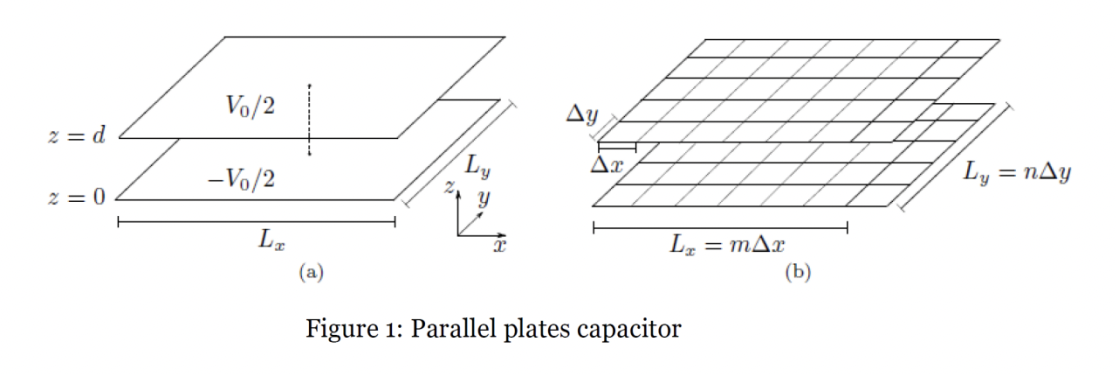

The method of moments is based on the integral expression for the potential generally given by:

$V\left(\vec{x} \right)=\frac{1}{4\pi \varepsilon_0 }\int \frac{\rho_s \left(\vec{x} \prime \right)}{|\vec{x} -\vec{x} \prime |}\mathrm{dS}\prime$    (Eq. 1)

where the integral is over a surface charge density. This problem can be simplified by dividing each of the two capacitor plates into $N=m\times n$rectangular regions of size $\Delta x\times \Delta y$, as shown in Fig. 1b. If one considers that $\rho_s$ is constant in the small rectangular region and equal to $\rho_j$ in each rectangele $j,j=1,\ldotp \ldotp \ldotp ,2N$, the integral in Eq. (1), can be approximated by:

$V\left(\vec{x} \right)=\frac{1}{4\pi \varepsilon_0 }\sum_{j=1}^{2N} \int_{S_j } \frac{\rho_j }{|\vec{x} -\vec{x} \prime |}\mathrm{dS}\prime$    (Eq. 2)

where $S_j$ corresponds to the rectangular region $j$. The $\rho_j$’s are $2N$ unknown charge densities ($N$ unknowns for each of the plate) for which we seek a solution. The sum operator on the right hand side of Eq. (2) indicates that potential at specific region is the sum of the contributions of charge distribution from all other $\Delta x\times \Delta y$ elements (including itself). Assume the left hand side of Eq. (2) is sampled at the center of each $2N$ rectangular region, which are noted as ${\vec{x} }_i$ for $i=1,\ldotp \ldotp \ldotp ,2N$, then the system equations can be written as:

$V\left({\vec{x} }_i \right)=\frac{1}{4\pi \varepsilon_0 }\sum_{j=1}^{2N} \int_{S_j } \frac{\rho_j }{|{\vec{x} }_i -\vec{x} \prime |}\mathrm{dS}\prime ,\;i=1,\ldotp \ldotp \ldotp ,2N$    (Eq. 3)

Now there are $2N$ equations (for each $i$) and $2N$ unknowns (for each $j$), the linear equations system can have a unique solution. The system of equations in Eq. (3) can be written in matrix form as:

$V=\mathrm{ZQ}$    (Eq. 4)

where $V$ is a column vector of length $2N$ whose $i^{\mathrm{th}}$ element is$V\left({\vec{x} }_i \right)$ (set by the potentials of the plate), $Q$ is a column vector of length $2N$ whose $j^{\mathrm{th}}$ elements is $\rho_j$ (the charges we are trying to determine) and $Z$ is a matrix which relates the two with elements given by:

$Z_{\mathrm{ij}} =\frac{1}{4\pi \varepsilon_0 }\int_{S_j } \frac{1}{|{\vec{x} }_i -\vec{x} \prime |}\mathrm{dS}\prime$.    (Eq. 5)

If $i\not= j$ then $Z_{\mathrm{ij}}$ can be approximated by:

$Z_{\mathrm{ij}} =\frac{1}{4\pi \varepsilon_0 }\frac{\Delta x\Delta y}{|{\vec{x} }_i -{\vec{x} }_j |}$    (Eq. 6)

If $i=j$, Eq. (6) no longer works and it can be shown that, in the case where $\Delta x=\Delta y$,

$Z_{\mathrm{ij}} =\frac{\Delta {\mathrm{xsinh}}^{-1} \left(1\right)}{\pi \varepsilon_0 }$    (Eq. 7)

*(a) For the capacitor in Fig. 1, with *$V_0 =2V$*, *$d=10\;\mathrm{cm}$*, *$L_x =50\;\mathrm{cm}$* and *$L_y =50\;\mathrm{cm}$*, subdivide each plate into squares as shown in Fig. 1b such that *$m=50$* and *$n=50$*. Use the ****method of moments**** to solve for the surface charge density (note that *$\Delta x=\Delta y$* such that Eq. (7) is applicable). Here vector *$V$* and matrix *$Z$* are established by the problem and the unknown matrix *$Q$* is determined by solving *$\mathrm{ZQ}=V$*. Do a surface plot of the charge density on each of the two plates. Find the capacitance *$C$* of the capacitor from your numerical solution via *$C=\frac{Q_t }{\Delta V}$*, where *$Q_t$* is the total charge on each plate.   *

Vo = 2;
d = 0.1;            % distance
Lx = 0.5;           % width
Ly = 0.5;           % height
m = 50;             % num of col
n = 50;             % num of row
dx = Lx/m;          % width of each pixel
dy = Ly/n;          % height of each pixel
Eo = 8.854e-12;     % permittivity of free space
N = m*n;            % total pixels
np = 2;             % num of plates
count = 0;
for np = 1:np
    for m = 1:m
        for n = 1:n
            count = count + 1;
            x(count,1) = m*dx;
            x(count,2) = n*dy;
            x(count,3) = np*d;
        end
    end
end

for n = 1:2*N
    for m = 1:2*N
        if (n==m)
            Z(n,m) = (dx*asinh(1))/(pi*Eo);
        else
            Z(n,m) = (1/(4*pi*Eo))*((dx*dy)/norm(x(n,1:3)-x(m,1:3)));
        end
    end
end
Z = Z

Z = 1.0e+08 *

    3.1686    0.8988    0.4494    0.2996    0.2247    0.1798    0.1498    0.1284    0.1123    0.0999    0.0899    0.0817    0.0749    0.0691    0.0642    0.0599    0.0562    0.0529    0.0499    0.0473    0.0449    0.0428    0.0409    0.0391    0.0374    0.0360    0.0346    0.0333    0.0321    0.0310    0.0300    0.0290    0.0281    0.0272    0.0264    0.0257    0.0250    0.0243    0.0237    0.0230    0.0225    0.0219    0.0214    0.0209    0.0204    0.0200    0.0195    0.0191    0.0187    0.0183
    0.8988    3.1686    0.8988    0.4494    0.2996    0.2247    0.1798    0.1498    0.1284    0.1123    0.0999    0.0899    0.0817    0.0749    0.0691    0.0642    0.0599    0.0562    0.0529    0.0499    0.0473    0.0449    0.0428    0.0409    0.0391    0.0374    0.0360    0.0346    0.0333    0.0321    0.0310    0.0300    0.0290    0.0281    0.0272    0.0264    0.0257    0.0250    0.0243    0.0237    0.0230    0.0225    0.0219    0.0214    0.0209    0.0204    0.0200    0.0195    

V = zeros(2*N,1);
V(1:N) = Vo/2;
V(N+1:2*N) = -Vo/2;
V = V

V =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Q = linsolve(Z,V)

Q = 1.0e-08 *

    0.1289
    0.0858
    0.0787
    0.0748
    0.0725
    0.0710
    0.0699
    0.0692
    0.0686
    0.0681


Q_top = Q(1:N);
Q_bottom = Q(N+1:2*N);

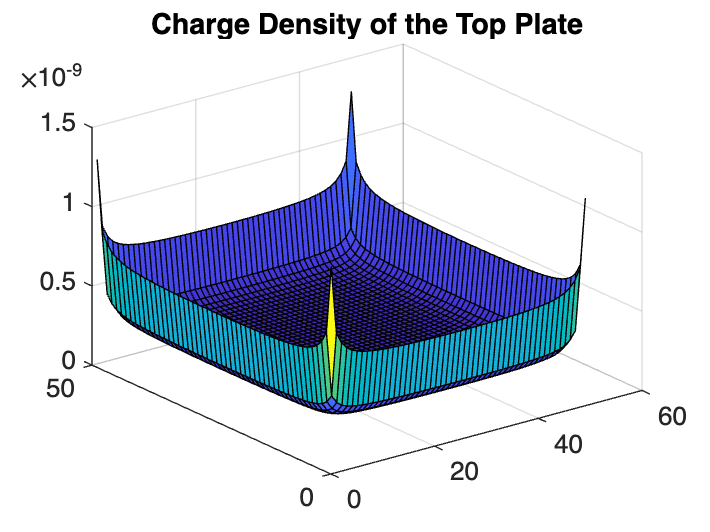

n = 50;
m = 50;
x = 1:m;
y = 1:n;

Q_top_mat = reshape(Q_top,[50,50]);
surf(x,y,Q_top_mat)
title('Charge Density of the Top Plate')

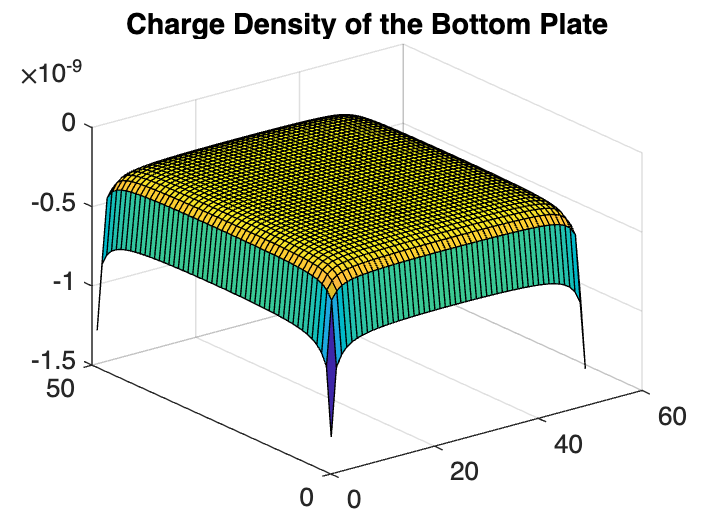

Q_bottom_mat = reshape(Q_bottom,[50,50]);
surf(x,y,Q_bottom_mat)
title('Charge Density of the Bottom Plate')

**The capacitance **$C$** of the capacitor**

C = (sum(Q(1:N))*dx*dy)/Vo

C = 3.4272e-11

*(b) Give a qualitative explanation from physical point of view about why charge accumulates at edge of the plate. Think about the electric fields and hence the potential at the edges if the charge density stayed uniform.*

To maintain a constant potential along the plate, the charges inside the conductor redistribute themselves in order for the electric field inside the conductor to be zero. As the free charges reach the surface, they cannot leave and therefore they just move around the surface. At the edge, the radius of curvature is small compared to the center of the plate. As the radius decreases, the differential surface area also decreases by a factor of . Since a charge density is a measure of charge per surface area, as the differential surface area decreases, we need a greater number of charge in a differential area if the charge density stayed uniform. Thus, the charge accumulates at the edge of the plate.

*(c) Using the code and parameters developed in problem (a) calculate capacitance for the following *$L_x$* and *$L_y$* values *$L_x =100\;\mathrm{cm}$* and *$L_y =25\;\mathrm{cm}$* (*$m=100$* and *$n=25$*) which is the same area as in (a). *

Vo = 2;
d = 0.1;            % distance
Lx = 1;             % width
Ly = 0.25;          % height
m = 100;            % num of col
n = 25;             % num of row
dx = Lx/m;          % width of each pixel
dy = Ly/n;          % height of each pixel
Eo = 8.854e-12;     % permittivity of free space
N = m*n;            % total pixels
np = 2;             % num of plates
count = 0;
for np = 1:np
    for m = 1:m
        for n = 1:n
            count = count + 1;
            x(count,1) = m*dx;
            x(count,2) = n*dy;
            x(count,3) = np*d;
        end
    end
end

for n = 1:2*N
    for m = 1:2*N
        if (n==m)
            Z(n,m) = (dx*asinh(1))/(pi*Eo);
        else
            Z(n,m) = (1/(4*pi*Eo))*((dx*dy)/norm(x(m,1:3)-x(n,1:3)));
        end
    end
end

V = zeros(2*N,1);
V(1:N) = Vo/2;
V(N+1:2*N) = -Vo/2;

Q = linsolve(Z,V);
Q_top = Q(1:N);
Q_bottom = Q(N+1:2*N);

C = (sum(Q(1:N))*dx*dy)/Vo

C = 3.6515e-11

*(d) Compare these results for both the with the capacitance values obtained in (a) and (c) to the expression for infinitely large parallel plate approximation developed in class.*

Expression for infinitely large parallel plate approximation: $C=\frac{\varepsilon_0 A}{d}=\frac{\varepsilon_0 L_x L_y }{d}$


$$\matrix{
\text{ }    &d     & L_x  	& L_y 	&C_\text{calculated}    &C_\text{expression}
\cr
\text{(a)}    &\text{10 cm}    &\text{50 cm}    &\text{50 cm}    &3.4272\times10^{-11}F     &2.2135\times10^{-11}F 		
\cr
\text{(c)}    &\text{10 cm}    &\text{100 cm}    &\text{25 cm}    &3.6515\times10^{-11}F   &2.2135\times10^{-11}F 
\cr
}$$


Both of the capacitance values obtained from the code have errors of a magnitude of 4. This might happen because of the assumptions that the expression above does not hold in our case. This expression assumes that we have an infinitely large area, while the case in (a) and (c) we have $A=25\;m$ (not big enough to be considered as infinite).

For the case (a), the capacitance value obtained from the code has a $54\ldotp 8%$ of error with respect to the $C$ value obtained from the infinitely large parallel plate approximation. While for (c), the capacitance value obtained from the code has a $64\ldotp 8%$ of error with respect to the $C$ value obtained from the infinitely large parallel plate approximation. The error between these two cases is $10%$, even though both have the same area.

*(e) Calculate the capacitance for *$d=2\mathrm{cm}$*, *$L_x =50\;\mathrm{cm}$* and *$L_y =50\;\mathrm{cm}$* and compare to the expression for infinitely large parallel plate approximation.*

Vo = 2;
d = 0.02;           % distance
Lx = 0.5;           % width
Ly = 0.5;           % height
m = 50;             % num of col
n = 50;             % num of row
dx = Lx/m;          % width of each pixel
dy = Ly/n;          % height of each pixel
Eo = 8.854e-12;     % permittivity of free space
N = m*n;            % total pixels
np = 2;             % num of plates

count = 0;
for np = 1:np
    for m = 1:m
        for n = 1:n
            count = count + 1;
            x(count,1) = m*dx;
            x(count,2) = n*dy;
            x(count,3) = np*d;
        end
    end
end

for n = 1:2*N
    for m = 1:2*N
        if (n==m)
            Z(n,m) = (dx*asinh(1))/(pi*Eo);
        else
            Z(n,m) = (1/(4*pi*Eo))*((dx*dy)/norm(x(n,1:3)-x(m,1:3)));
        end
    end
end

V = zeros(2*N,1);
V(1:N) = Vo/2;
V(N+1:2*N) = -Vo/2;

Q = linsolve(Z,V);
Q_top = Q(1:N);
Q_bottom = Q(N+1:2*N);
C = (sum(Q(1:N))*dx*dy)/Vo

C = 1.2884e-10


$$\begin{array}{l}
C_{\textrm{calculated}} =1\ldotp 2884\times {10}^{-10} F\\
C_{\exp } =\frac{\varepsilon_0 A}{d}=1\ldotp 1068\times {10}^{-10} F
\end{array}$$


The capacitance value obtained from the code has a $16\ldotp 4%$ error with respect to the $C$ value obtained from the infinitely large parallel plate approximation. The accuracy of the approximation improved by $38\ldotp 4%$ compared to the result in case (a). Here, the distance was decreased to $2\;\mathrm{cm}$ and therefore, the capacitance value increased by a magnitude of 1, since capacitance is inversely proportional with the separation of the plates.

*(f) Discuss the trends in the results and why certain geometries are better approximated by the infinitely large parallel plate approximation developed in class.*

We saw that the calculated capacitance is closer to the capacitance obtained from the expression in the case where the distance between the two plates is $2\;\mathrm{cm}$. This happens because when the plates are much closer together, the edge of the plates is far away in comparison to the distance between the charges on the two plates. Therefore, we can neglect the effect of ununiform distribution of charge in the edge of the plates (discovered in part (a)). As a result, we can assume that the electric field is constant along the plates. In consequence, we can also assume a constant potential in every point on the plate. This is evident as we got a slightly better approximation in part (a) compared to part (c) because any point on the plates in case (a) is farther away from the edge, due to the geometry of the plate being a squared shape.